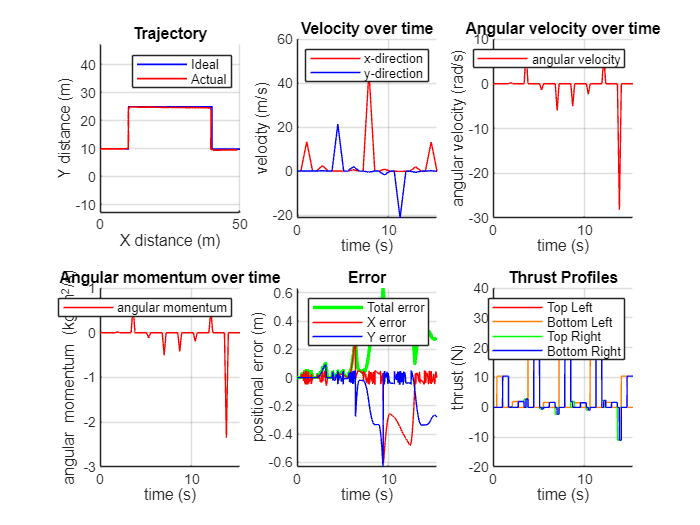


% ===== AUTHORS ===== %
% - Liam Murray
% - Sofia Simas
% - Lilly Mertzluft
% - Summer Chirpich
% - Satvik Kumar



% ===== INIT ========= %

clear
clc

[targetTime, targetPosX, targetPosY] = obstaclePath();
%[targetTime, targetPosX, targetPosY] = R_path();
astrobee = generateAstrobeeStruct();
dt = 0.0001;

% ===== SIMULATE ===== %

thrustProfiles = solveThrustProfiles(targetTime, targetPosX, targetPosY, astrobee, dt);
[time, posX, posY, velX, velY, theta, omega] = solvePath(astrobee, thrustProfiles);
[errorTime, posError, errorX, errorY] = getError(time, posX, posY, targetTime, targetPosX, targetPosY);

% ===== DISPLAY ===== %
makePlots(time, targetTime, targetPosX, targetPosY, posX, posY, velX, velY, theta, omega, errorTime, posError, errorX, errorY, thrustProfiles, dt, astrobee);

renderAnimation(time, targetTime, targetPosX, targetPosY, posX, posY, theta, thrustProfiles, astrobee);
